# 1. Matrix "gupta3"

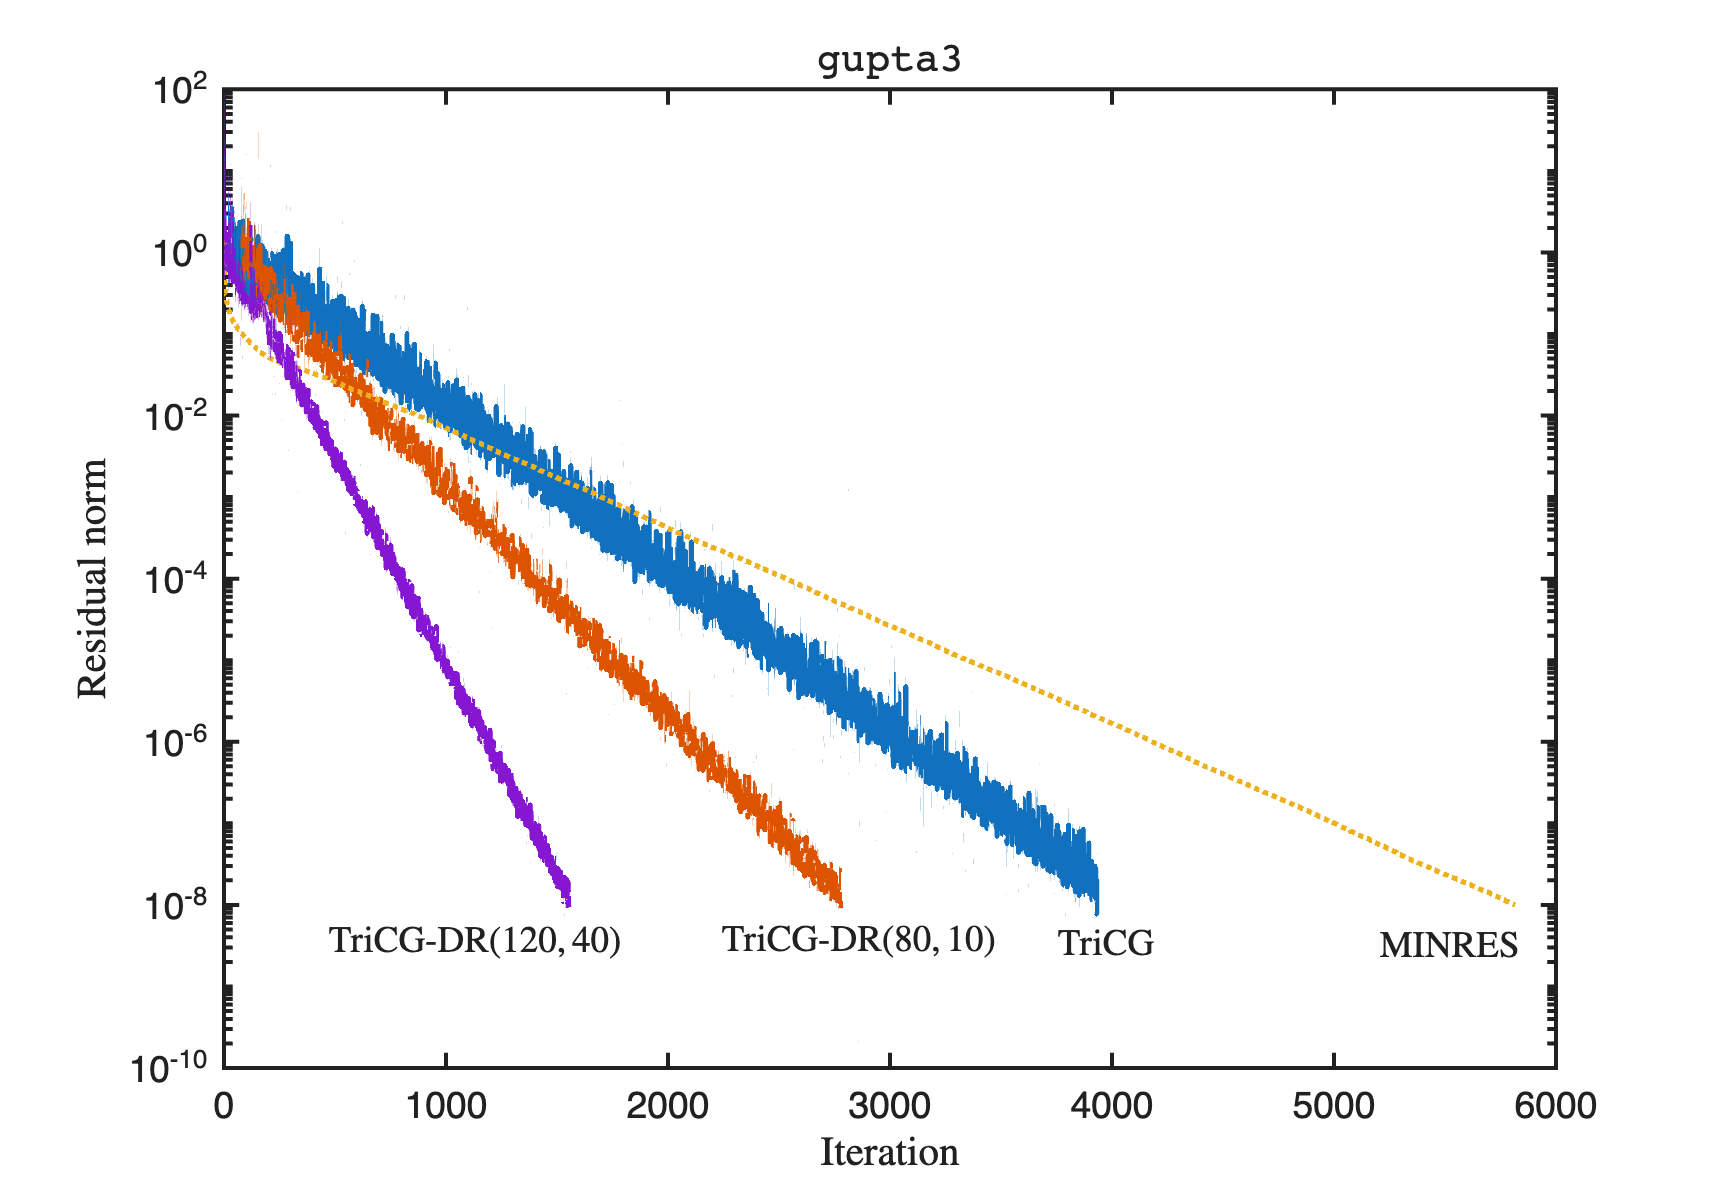

clc; close all; clearvars;

mat_name = "gupta3";
load("mats" + filesep + mat_name + ".mat");
A = Problem.A;

[m, n] = size(A);

b = ones(m, 1);
c = ones(n, 1);
b = b / norm(b);
c = c / norm(c);

k1 = 10;
p1 = 80;
k2 = 40;
p2 = 120;
tol = 1e-8;
stol = 1e-10;
exres = true;
maxcycle = 10;
maxit = 80000;

[~, ~, ~, resvec1] = tricg(A, b, c, [], [], tol, maxit, exres=exres);
[~, ~, ~, resvec2] = tricgdr(A, b, c, [], [], k1, p1, tol, maxcycle, ...
    maxit=maxit, stol=stol, exres=exres);
[~, ~, ~, resvec3] = tricgdr(A, b, c, [], [], k2, p2, tol, maxcycle, ...
    maxit=maxit, stol=stol, exres=exres);

K = [speye(m), A; A', -speye(n)];
[~, ~, resvec4] = minres(K, [b; c], [], tol, maxit, exres=exres);

default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 860 600]);

f1 = semilogy(0:length(resvec1)-1, resvec1, LineStyle='-');
hold on;
f2 = semilogy(0:length(resvec2)-1, resvec2, LineStyle='--');
f3 = semilogy(0:length(resvec4)-1, resvec4, LineStyle=':');
f4 = semilogy(0:length(resvec3)-1, resvec3, LineStyle='-.');
hold off;

title_name = replace(mat_name, '_', '\_');
title(sprintf('\\texttt{%s}', title_name), Interpreter='latex', FontSize=18);
xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
% legend([f1, f3, f2, f4], {'TriCG', 'MINRES', ...
%     sprintf('TriCG-DR$(%d,%d)\\,$', p1, k1), sprintf('TriCG-DR$(%d,%d)\\,$', p2, k2)}, ...
%     Location='northeast', Interpreter='latex', FontSize=14);
annotation("textbox", [0.792 0.1899 0.07852 0.04874], "String", "MINRES", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.6048 0.1916 0.07852 0.04874], "String", "TriCG", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.4097 0.195 0.07852 0.04874], "String", "TriCG-DR$(80,10)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.1812 0.1934 0.07852 0.04874], "String", "TriCG-DR$(120,40)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");


exportgraphics(gcf, sprintf('figs/fig2_%s.pdf', mat_name), Resolution=600);

# 2. Matrix "g7jac060sc"

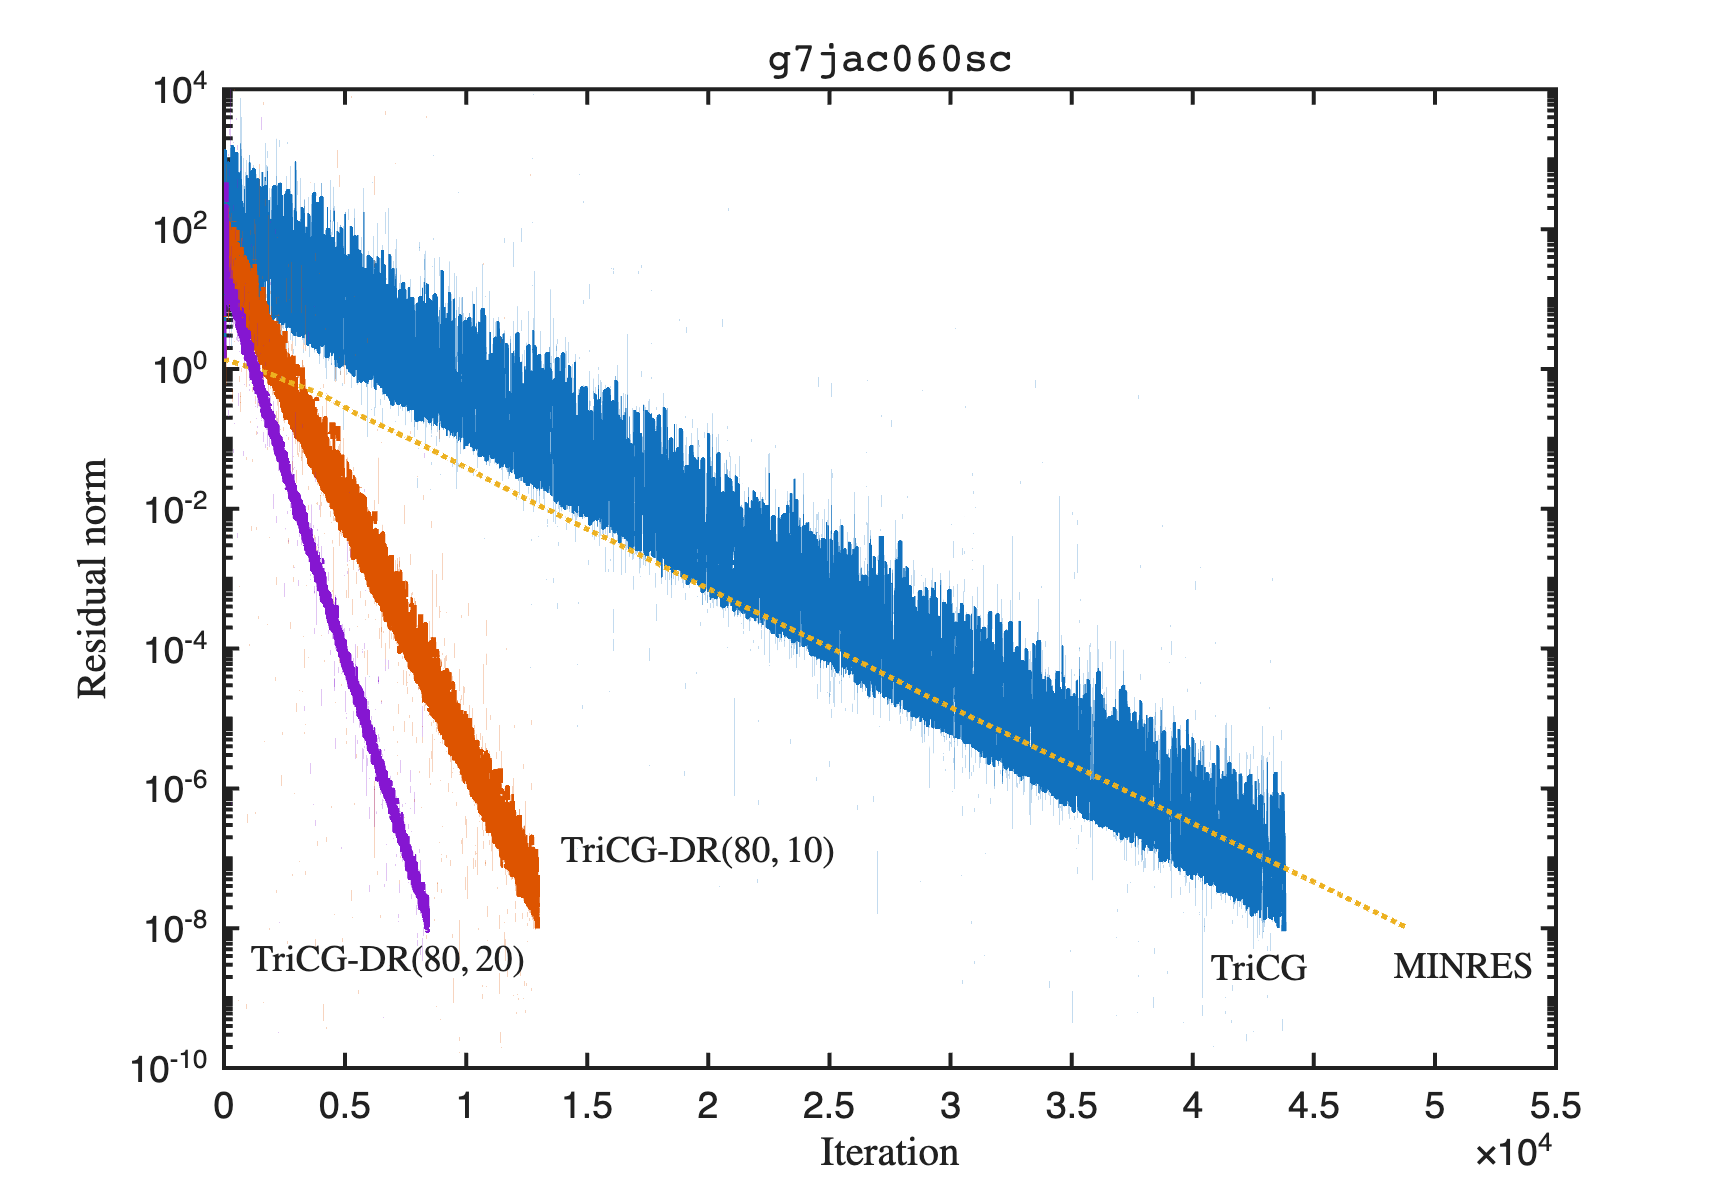

clc; close all; clearvars;

mat_name = "g7jac060sc";
load("mats" + filesep + mat_name + ".mat");
A = Problem.A;

[m, n] = size(A);

b = ones(m, 1);
c = ones(n, 1);
b = b / norm(b);
c = c / norm(c);

k1 = 10;
p1 = 80;
k2 = 20;
p2 = 80;
tol = 1e-8;
stol = 1e-10;
exres = true;
maxcycle = 10;
maxit = 80000;

[~, ~, ~, resvec1] = tricg(A, b, c, [], [], tol, maxit, exres=exres);
[~, ~, ~, resvec2] = tricgdr(A, b, c, [], [], k1, p1, tol, maxcycle, ...
    maxit=maxit, stol=stol, exres=exres);
[~, ~, ~, resvec3] = tricgdr(A, b, c, [], [], k2, p2, tol, maxcycle, ...
    maxit=maxit, stol=stol, exres=exres);

K = [speye(m), A; A', -speye(n)];
[~, ~, resvec4] = minres(K, [b; c], [], tol, maxit, exres=exres);

default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 860 600]);

f1 = semilogy(0:length(resvec1)-1, resvec1, LineStyle='-');
hold on;
f2 = semilogy(0:length(resvec2)-1, resvec2, LineStyle='--');
f3 = semilogy(0:length(resvec4)-1, resvec4, LineStyle=':');
f4 = semilogy(0:length(resvec3)-1, resvec3, LineStyle='-.');
hold off;

xlim([0, 55000]);
title_name = replace(mat_name, '_', '\_');
title(sprintf('\\texttt{%s}', title_name), Interpreter='latex', FontSize=18);
xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
% legend([f1, f3, f2, f4], {'TriCG', 'MINRES', ...
%     sprintf('TriCG-DR$(%d,%d)\\,$', p1, k1), sprintf('TriCG-DR$(%d,%d)\\,$', p2, k2)}, ...
%     Location='northeast', Interpreter='latex', FontSize=14);
annotation("textbox", [0.8005 0.1725 0.1138 0.04874], "String", "MINRES", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.6941 0.1708 0.0903 0.04874], "String", "TriCG", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.3158 0.269 0.1735 0.04874], "String", "TriCG-DR$(80,10)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.1359 0.1776 0.1735 0.04874], "String", "TriCG-DR$(80,20)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");



exportgraphics(gcf, sprintf('figs/fig2_%s.pdf', mat_name), Resolution=600);

# 3. Matrix "rajat27"

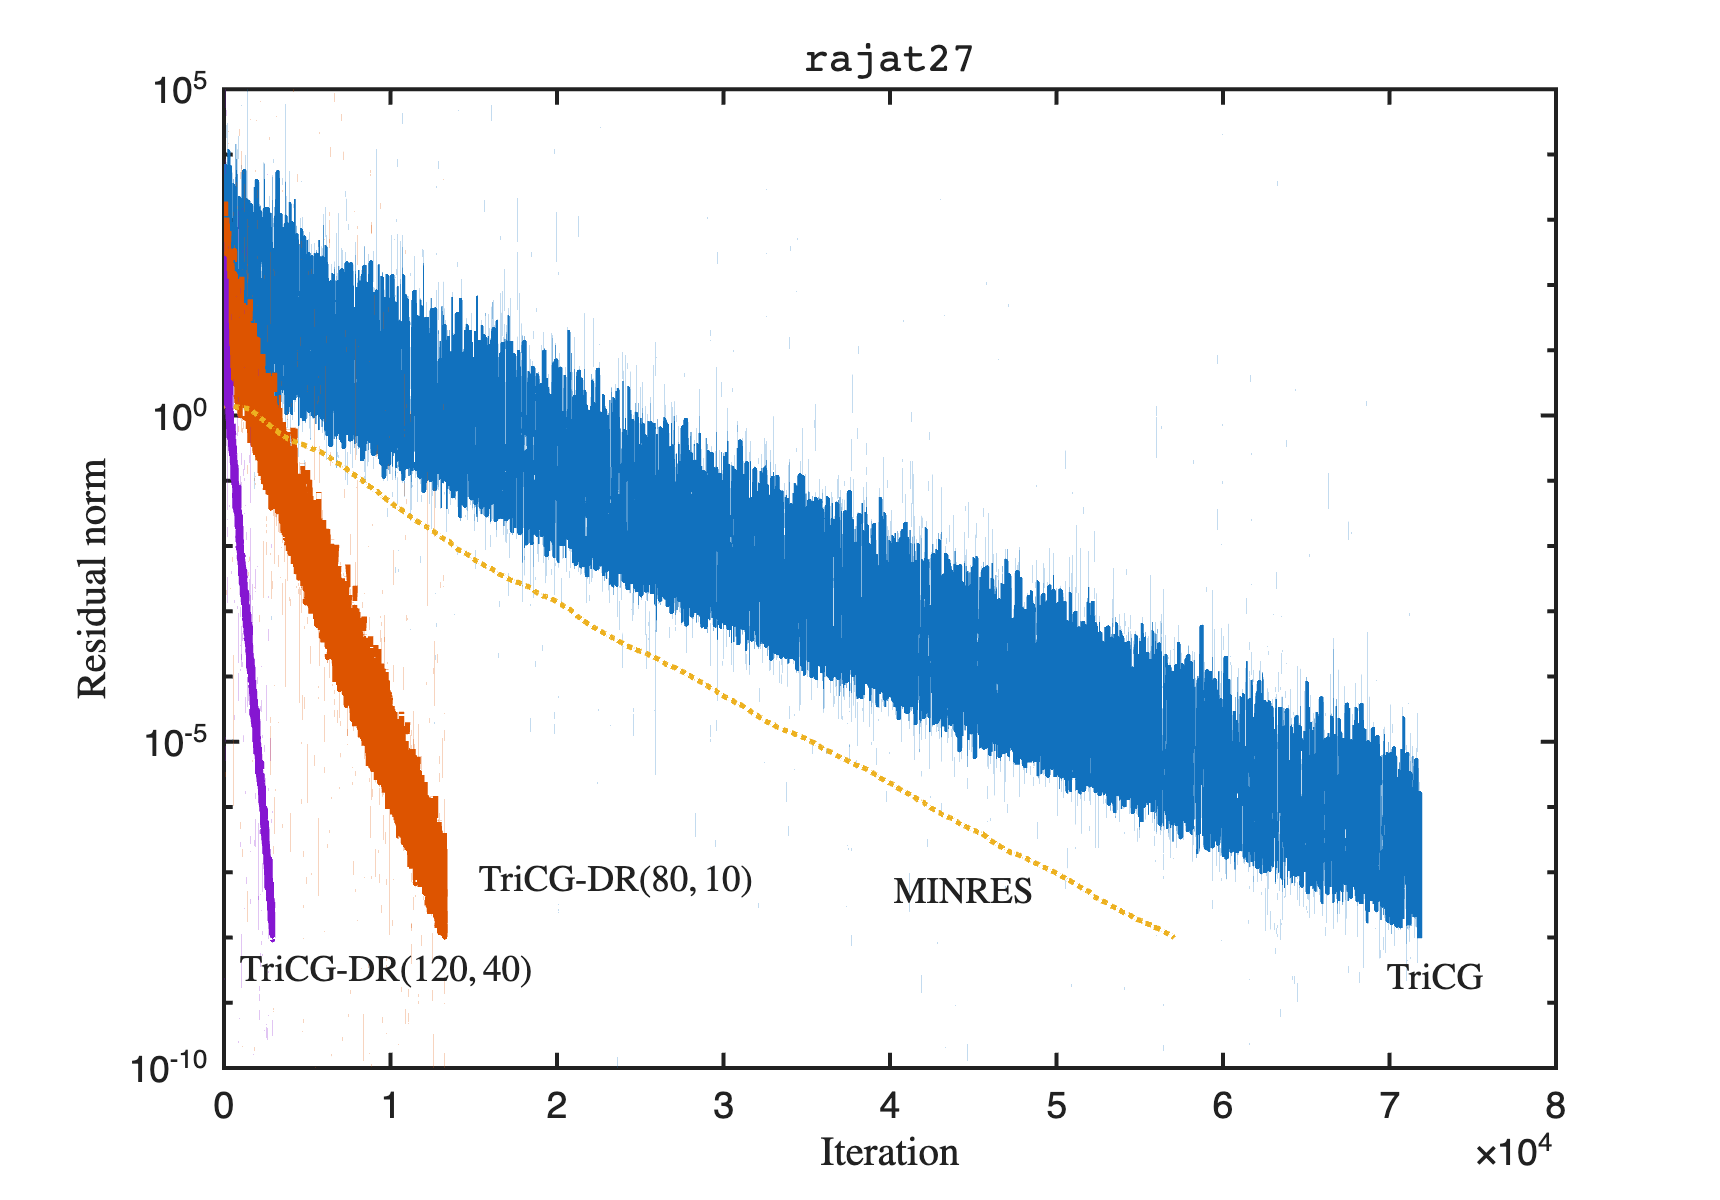

clc; close all; clearvars;

mat_name = "rajat27";
load("mats" + filesep + mat_name + ".mat");
A = Problem.A;

[m, n] = size(A);

b = ones(m, 1);
c = ones(n, 1);
b = b / norm(b);
c = c / norm(c);

k1 = 10;
p1 = 80;
k2 = 40;
p2 = 120;
tol = 1e-8;
stol = 1e-10;
exres = true;
maxcycle = 10;
maxit = 80000;

[~, ~, ~, resvec1] = tricg(A, b, c, [], [], tol, maxit, exres=exres);
[~, ~, ~, resvec2] = tricgdr(A, b, c, [], [], k1, p1, tol, maxcycle, ...
    maxit=maxit, stol=stol, exres=exres);
[~, ~, ~, resvec3] = tricgdr(A, b, c, [], [], k2, p2, tol, maxcycle, ...
    maxit=maxit, stol=stol, exres=exres);

K = [speye(m), A; A', -speye(n)];
[~, ~, resvec4] = minres(K, [b; c], [], tol, maxit, exres=exres);

default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 860 600]);

f1 = semilogy(0:length(resvec1)-1, resvec1, LineStyle='-');
hold on;
f2 = semilogy(0:length(resvec2)-1, resvec2, LineStyle='--');
f3 = semilogy(0:length(resvec4)-1, resvec4, LineStyle=':');
f4 = semilogy(0:length(resvec3)-1, resvec3, LineStyle='-.');
hold off;

title_name = replace(mat_name, '_', '\_');
title(sprintf('\\texttt{%s}', title_name), Interpreter='latex', FontSize=18);
xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
% legend([f1, f3, f2, f4], {'TriCG', 'MINRES', ...
%     sprintf('TriCG-DR$(%d,%d)\\,$', p1, k1), sprintf('TriCG-DR$(%d,%d)\\,$', p2, k2)}, ...
%     Location='northeast', Interpreter='latex', FontSize=14);
annotation("textbox", [0.7964 0.163 0.0903 0.04866], "String", "TriCG", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.5098 0.2347 0.1138 0.04866], "String", "MINRES", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.2682 0.2127 0.1576 0.08066], "String", "TriCG-DR$(80,10)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.1293 0.1376 0.1676 0.08066], "String", "TriCG-DR$(120,40)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");


exportgraphics(gcf, sprintf('figs/fig2_%s.pdf', mat_name), Resolution=600);

# 4. Matrix "TSOPF_RS_b300_c2"

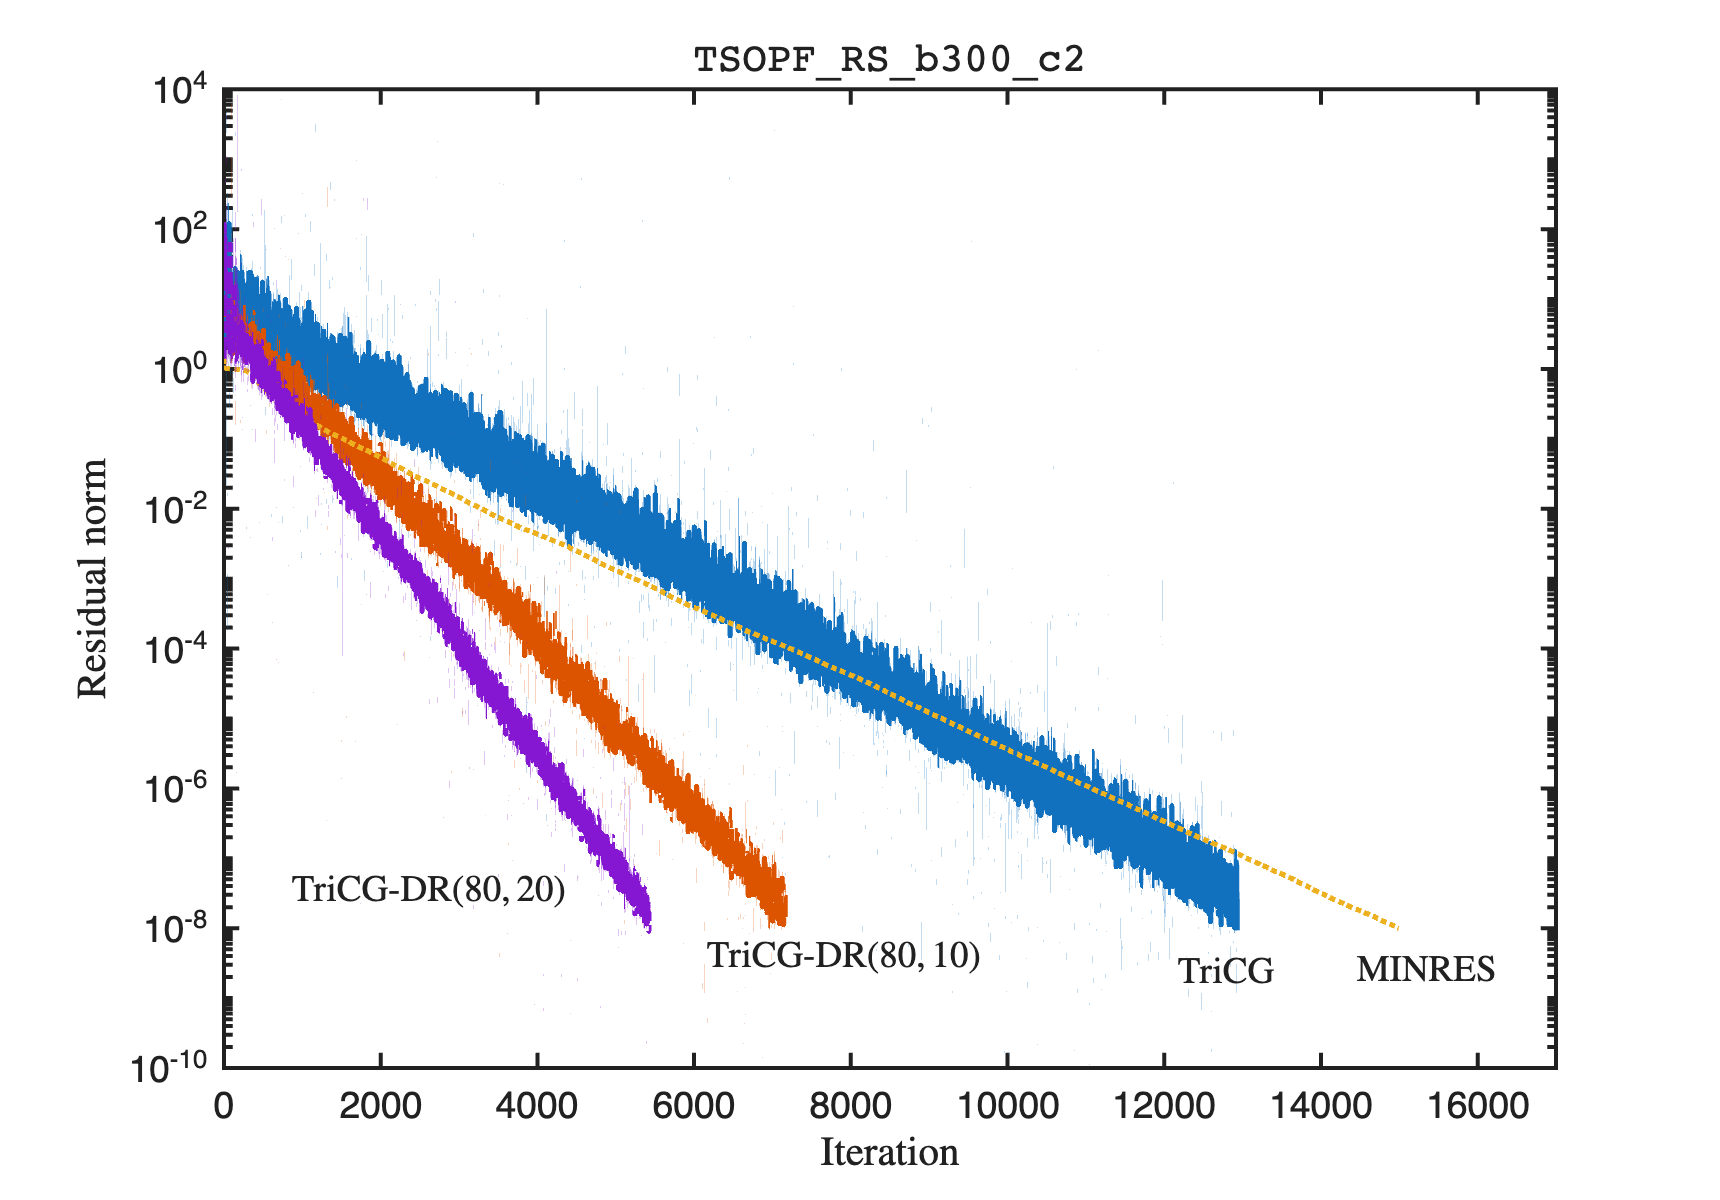

clc; close all; clearvars;

mat_name = "TSOPF_RS_b300_c2";
load("mats" + filesep + mat_name + ".mat");
A = Problem.A;

[m, n] = size(A);

b = ones(m, 1);
c = ones(n, 1);
b = b / norm(b);
c = c / norm(c);

k1 = 10;
p1 = 80;
k2 = 20;
p2 = 80;
tol = 1e-8;
stol = 1e-10;
exres = true;
maxcycle = 10;
maxit = 80000;

[~, ~, ~, resvec1] = tricg(A, b, c, [], [], tol, maxit, exres=exres);
[~, ~, ~, resvec2] = tricgdr(A, b, c, [], [], k1, p1, tol, maxcycle, ...
    maxit=maxit, stol=stol, exres=exres);
[~, ~, ~, resvec3] = tricgdr(A, b, c, [], [], k2, p2, tol, maxcycle, ...
    maxit=maxit, stol=stol, exres=exres);

K = [speye(m), A; A', -speye(n)];
[~, ~, resvec4] = minres(K, [b; c], [], tol, maxit, exres=exres);

default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 860 600]);

semilogy(0:length(resvec1)-1, resvec1, LineStyle='-');
hold on;
semilogy(0:length(resvec2)-1, resvec2, LineStyle='--');
semilogy(0:length(resvec4)-1, resvec4, LineStyle=':');
semilogy(0:length(resvec3)-1, resvec3, LineStyle='-.');
hold off;

xlim([0, 17000]);
title_name = replace(mat_name, '_', '\_');
title(sprintf('\\texttt{%s}', title_name), Interpreter='latex', FontSize=18);
xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
% legend([f1, f3, f2, f4], {'TriCG', 'MINRES', ...
%     sprintf('TriCG-DR$(%d,%d)\\,$', p1, k1), sprintf('TriCG-DR$(%d,%d)\\,$', p2, k2)}, ...
%     Location='northeast', Interpreter='latex', FontSize=14);

annotation("textbox", [0.675 0.168 0.0903 0.04866], "String", "TriCG", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.7789 0.1697 0.1138 0.04866], "String", "MINRES", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.4009 0.1493 0.1576 0.08066], "String", "TriCG-DR$(80,10)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.1595 0.2044 0.1576 0.08066], "String", "TriCG-DR$(80,20)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");


exportgraphics(gcf, sprintf('figs/fig2_%s.pdf', mat_name), Resolution=600);